% Value Generation

subjective_probs = modified_beta_inverse_cdf(rand(1,1e3),.625,.03);
bet_amounts = 7.5*ones(1,1e3); 

[player_struct,~] = mark_1_gambling_system(subjective_probs,bet_amounts,2);
mark1_system_metrics = gambling_system_checker(player_struct,bet_amounts);

[player_struct,~] = moneyline_gambling_system(subjective_probs,bet_amounts);
moneyline_system_metrics = gambling_system_checker(player_struct,bet_amounts);

mark1_expected_values = mark1_system_metrics.subjective_expectations./bet_amounts;
moneyline_expected_values = moneyline_system_metrics.subjective_expectations./bet_amounts;
[~,sort_indeces] = sort(subjective_probs);


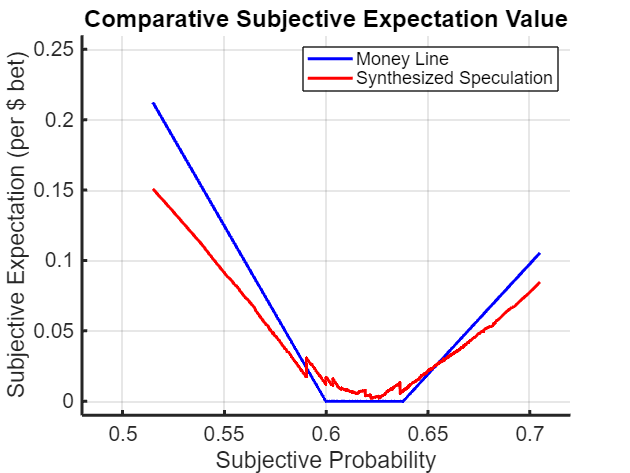

% Plotting

figure
hold on
plot(subjective_probs(sort_indeces),moneyline_expected_values(sort_indeces),'Color',[0 0 1])
plot(subjective_probs(sort_indeces),mark1_expected_values(sort_indeces),'Color',[1 0 0])
xlabel('Subjective Probability','FontSize',16)
ylabel('Subjective Expectation (per $ bet)','FontSize',16)
title('Comparative Subjective Expectation Value')
legend({'Money Line','Synthesized Speculation'},'FontSize',12)
xlim([.48 .72])
ylim([-.01 .26])
sexy_plot

% Percent of Bets Covered

modified_beta_cdf(.65,.625,.03)-modified_beta_cdf(.59,.625,.03)

ans = 0.6647